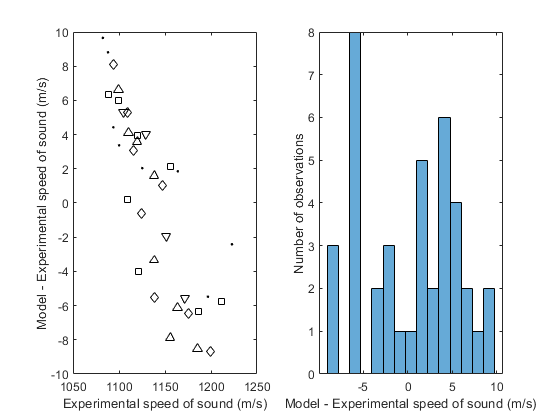

index_optimal_conditions = 11; %index for the for the optimal conditions. Change this manually
if numel(unique(LOOCV.Initial)) == 2
   optimal_conditions.index(:,1) = (1:4)';
   optimal_conditions.centring(:,1) = ["c";"r";"c";"r"];
   optimal_conditions.initial(:,1) = ["JR";"JR";"ideal";"ideal"];
   
   optimal_centering = optimal_conditions.centring(index_optimal_conditions);
   optimal_initial = optimal_conditions.initial(index_optimal_conditions);
else
   optimal_conditions.index(:,1) = (1:12)';
   optimal_conditions.centring(:,1) = ["c";"r";"c";"r";"c";"r";"c";"r";"c";"r";"c";"r"];
   optimal_conditions.initial(:,1) = ["c";"c";"r";"r";"all";"all";"rc";"rc";"JR";"JR";"ideal";"ideal"];
   
   optimal_centering = optimal_conditions.centring(index_optimal_conditions);
   optimal_initial = optimal_conditions.initial(index_optimal_conditions);
end

formatting = [".k", "sk", "dk", "^k", "vk"];
for z = 1:5
    iii = (LOOCV.Initial == optimal_initial & LOOCV.Centering == optimal_centering & LOOCV.Composition == z & LOOCV.Rank == Optimal_rank(index_optimal_conditions,z));
    subplot(1, 2, 1)
    plot(LOOCV.Original(iii), LOOCV.Itterations(iii)-LOOCV.Original(iii), formatting(z)); hold on
end
hold off; xlabel("Experimental speed of sound (m/s)");
ylabel("Model - Experimental speed of sound (m/s)")
filename = "Parity plots.jpg";
f = getframe(gcf);

%imwrite(f.cdata, fullfile(folder, filename));

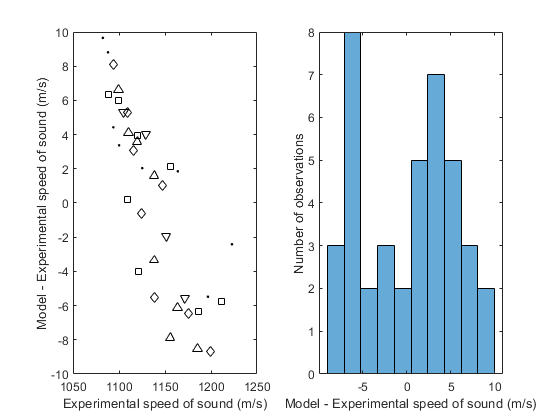

clear iii
iii = [];
for z = 1:5
    iii = [iii,(LOOCV.Initial == optimal_initial & LOOCV.Centering == optimal_centering & LOOCV.Composition == z & LOOCV.Rank == Optimal_rank(index_optimal_conditions,z))];
end
iii = sum(iii,2)>0;
subplot(1, 2, 2)
temp = LOOCV.Itterations(iii)-LOOCV.Original(iii);
bounds = 100;
greater = (temp > bounds);
less = -(temp < -bounds);
temp = temp.*(temp >= -bounds & temp <= bounds) + bounds*(greater + less);
histogram(temp, 10); hold off
xlabel("Model - Experimental speed of sound (m/s)")
ylabel("Number of observations")
filename = "Error distribution.jpg";
f = getframe(gcf);

%imwrite(f.cdata, fullfile(folder, filename));